
rosshutdown;
rosinit;

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
The value of the ROS_HOSTNAME environment variable, localhost, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_08551 with NodeURI http://localhost:38556/


clc
data=[];
[cmdpub,cmdmsg] = rospublisher('/cmd_vel','geometry_msgs/Twist');
% [cmdpub,cmdmsg] = rospublisher('tracker/position','geometry_msgs/Point');
% turn=[-1.5;-1;-0.5;0;0.5;1;1.5;2;2.5];
turn_init=mean(rpy(1:10,2));
for i = 2:length(trajectory)
    
    cmdmsg.Linear.X = trajectory(i,1);
    cmdmsg.Linear.Y = 0;
    cmdmsg.Linear.Z = 0;
    cmdmsg.Angular.X = 0;
    cmdmsg.Angular.Y = 0;
    %     cmdmsg.Angular.Z = turn(i,1);
        cmdmsg.Angular.Z = (atan2((trajectory(i,3) - trajectory(i-1,3)),(trajectory(i,2) - trajectory(i-1,2)))-(turn_init));
%     cmdmsg.Angular.Z = (atan2((trajectory(i,3) - trajectory(i-1,3)),(trajectory(i,2) - trajectory(i-1,2))));
    % a · b = ax × bx + ay × by
    %             cmdmsg.Angular.Z = (((trajectory(i,3) * trajectory(i-1,3))+(trajectory(i,2) * trajectory(i-1,2))));
    
    fprintf('working...\r\n')
    send(cmdpub,cmdmsg)
    %     cmdpause = (peakdata(i,3) - peakdata(i-1,3))/50;
    cmdpause = (peakdata(i,3) - peakdata(i-1,3))/50;
    if cmdpause > 2
        cmdpause = 2;
    end
    
    pause(cmdpause)
    data=[data;i,cmdmsg.Linear.X,rad2deg(cmdmsg.Angular.Z),cmdpause];
    
end

working...
working...
working...
working...
working...
working...


cmdmsg.Linear.X = 0;
cmdmsg.Linear.Y = 0;
cmdmsg.Linear.Z = 0;
cmdmsg.Angular.X = 0;
cmdmsg.Angular.Y = 0;
cmdmsg.Angular.Z = 0;

fprintf('end.\r\n')

end.


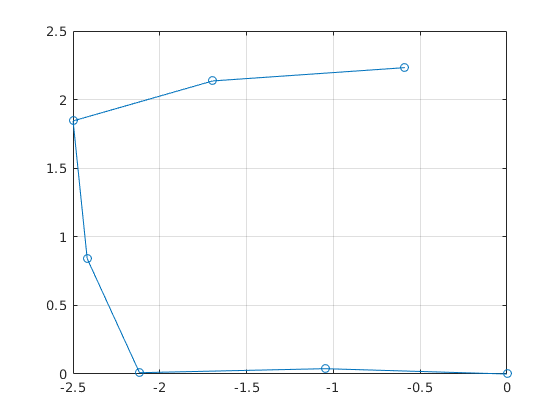

send(cmdpub,cmdmsg)

plot(trajectory(:,3),trajectory(:,2),'o-'),grid on